# Projektowanie metodą zer i biegunów

fq10rps = 0.1

fq10rps = 0.1000


p = [-0.5-1i*9.5, -1-1i*10, -0.5-1i*10.5, -0.5+1i*10.5, -1+1i*10, -0.5+1i*9.5];
z = [-1i*15, -1i*5, 1i*5, 1i*15];

w = (0:fq10rps:20-fq10rps) .* 1i;


Zera i bieguny na płaszczyźnie zespolonej:

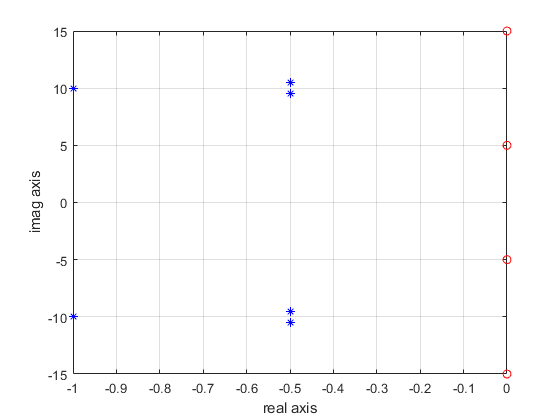

figure
plot(real(z),imag(z),'or')
hold on
plot(real(p),imag(p),'*b')
hold off

xlabel('real axis')
ylabel('imag axis')

grid on

wzor ze wstepu:

amp = 1;
bm = amp; an = amp;
Y = 1; X = 1;
for i=1:length(z)
    Y = Y .* (w-z(i));
end
for i=1:length(p)
    X = X .* (w-p(i));
end

H = (bm.*Y) ./ (an.*X);


Alternatywa

bm = poly(z);
an = poly(p);

Y = polyval(bm, w);

X = polyval(an, w);

H = Y ./ X;


pokazywanko

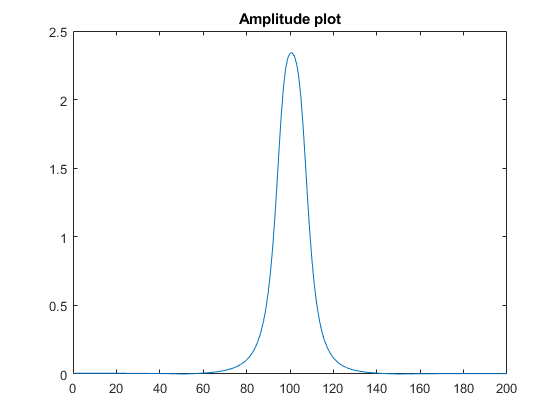

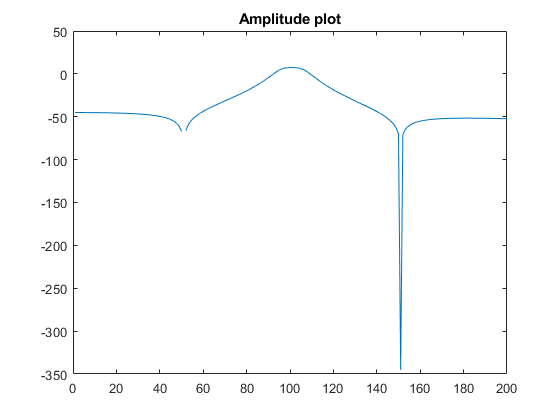

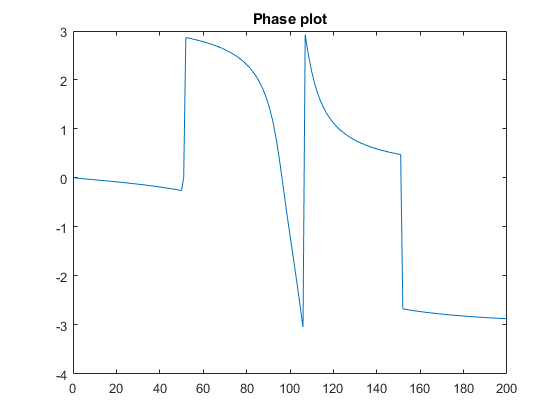

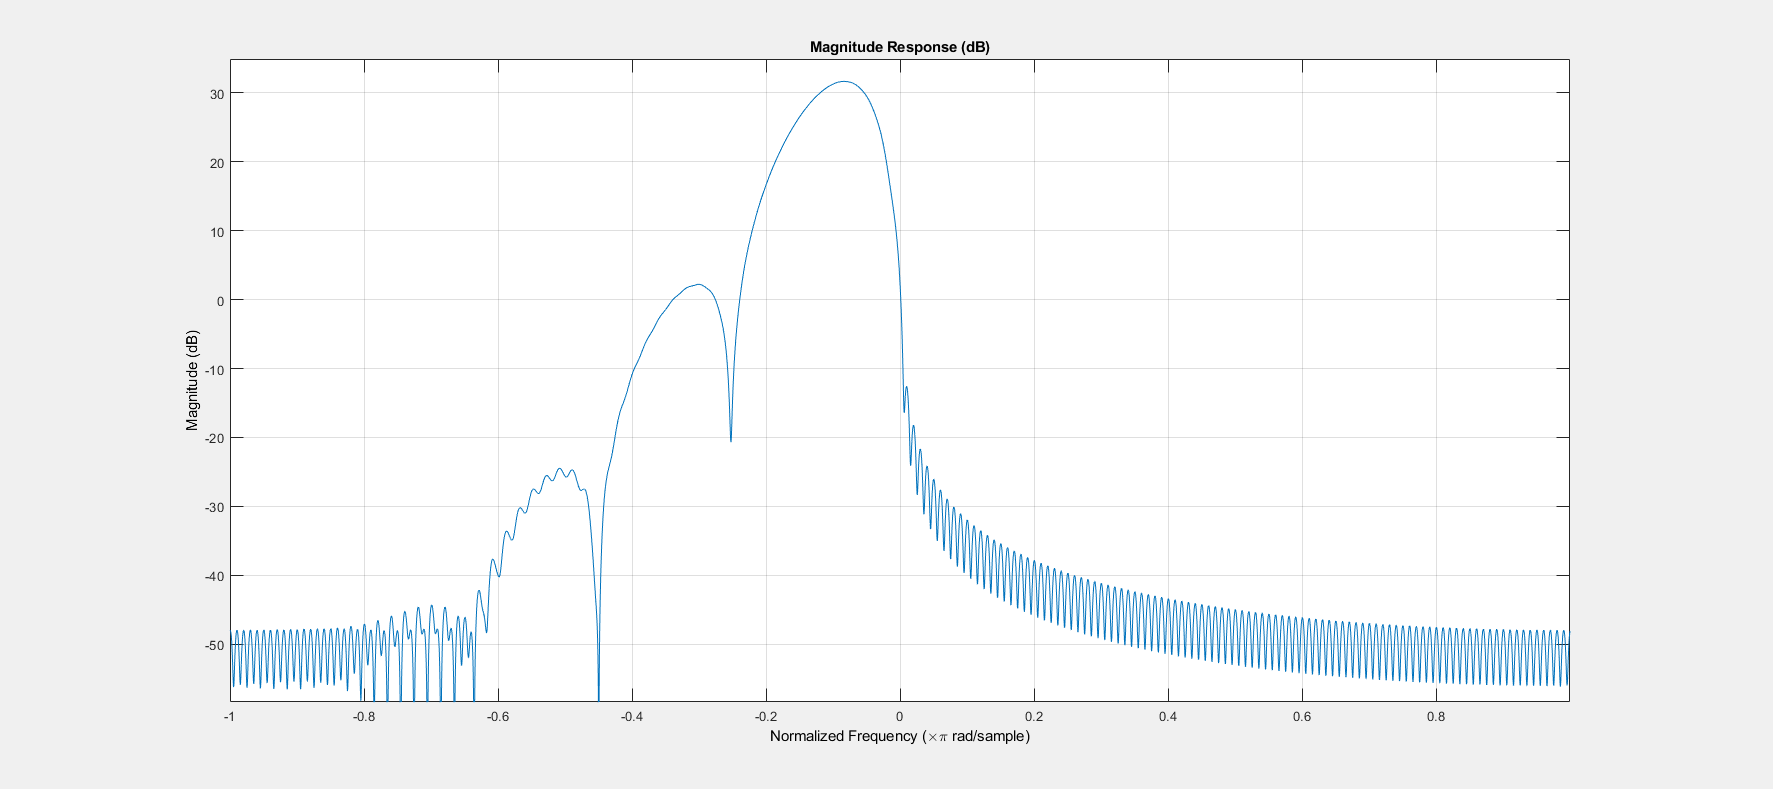

figure, plot(abs(H)), title('Amplitude plot')
figure, plot(20*log10(abs(H))), title('Amplitude plot')
figure, plot(angle(H)), title('Phase plot')
fvtool(H)